# 5. Processing 2D NMR COSY 

### Introduction

In the previous examples we looked at 1D NMR of substances. This can be extended into the second dimension. This method allows for a more detailed and informative exploration of molecular structures by correlating signals between different types of atoms or different regions within a molecule.

In 2D NMR, a series of radiofrequency pulses are applied, and the interactions between nuclear spins are recorded over two time periods, known as t1 (evolution period) and t2 (detection period). 

**1.Evolution Period** (t1): After the initial excitation, the system is allowed to evolve for a period of time, t1. During this time, the spins begin to accumulate phase coherence due to differences in their chemical shifts. This period is the key to introducing the second dimension.

**2.Mixing Sequence**: A specific sequence of additional RF pulses (known as the mixing sequence) is then applied. This sequence can vary depending on the type of 2D NMR experiment being conducted (e.g., COSY, NOESY, HSQC). The purpose of these pulses is to move magnetization to a different spin.

**3.Detection Period (t2)**: Following the mixing sequence, the signal is detected over a second time period, t2. This detection is similar to the process in 1D NMR, where the decay of the nuclear spin states (Free Induction Decay, or FID) is recorded.

By repeating the experiment and incrementing the evolution time t1 we record slightly different FIDs, reflecting the behavior of the nuclear spins during that specific t1 period.

The FIDs are concatenated with different rows for each t1. Then a Fourier transform is taken in the t2 dimension (Direct), followed by a Fourier transform in t1 (Indirect dimension) to create a spectrum in the frequency domain, holding the information on the signals. 

### **2D NMR COSY**

Let us import and process a vital 2D NMR technique known as **Homonuclear Correlation Spectroscopy (COSY).** COSY is a pivotal tool in the study of organic compounds, playing an essential role in the elucidation of molecular structures.

COSY primarily investigates the interactions between identical types of nuclei, most commonly hydrogen atoms 1H, though it can be applied to other nuclei as well. This technique hinges on the principle of nuclear spin coupling, which occurs between nuclei that are spatially close within a molecule, typically up to three bonds apart.

The COSY experiment transforms the conventional one-dimensional NMR spectrum into a two-dimensional array. In this 2D spectrum, one axis represents the chemical shift of one nucleus, while the other axis corresponds to the chemical shift of another nucleus. The key feature of a COSY spectrum is the presence of cross-peaks. These cross-peaks are essential as they indicate which nuclei are J-coupled, or scalar coupled, to each other. J-coupling is a through-bond interaction that provides critical insights into the connectivity of atoms within the molecule.

By analyzing these cross-peaks, chemists can determine the network of scalar couplings in the molecule, which in turn reveals how the atoms are linked together. This makes COSY especially powerful for deducing the skeleton of organic molecules, as it can distinguish between different types of protons and their respective environments in the molecule.

### Experimental data import

In this example we will look at a COSY of cyclosporine. It is a potent immunosuppressive drug widely used in post-allogeneic organ transplant. This NMR data is kindly provided by Prof. Ilya Kuprov, University of Southampton.

The dataset has already been exported by the NMR instrument into a MATLAB [MAT file](https://www.mathworks.com/help/matlab/ref/matlab.io.matfile.html) that may be loaded and plotted directly. 

load('Cyclosporine_COSY.mat');
timeSpectrum=data.Data;

When we want to identify the diagonal and cross-peaks For COSY experiments we can plot the absolute spectrum which is not phase sensitive. All peaks are positive and phase correction is not required.

figure()
% Lets fourier transform into the frequency domain see the raw plot of absolute magnitudes
smax_abs=max(abs(fft2((timeSpectrum))),[],'all');

2D spectra in MATLAB are stored as a 2D matrices holding the intensities at each point. These can be better visualized with 3D surface plots or contour plots. Let us try this with a non-linear level contour plot. The sensitivity of the contour plot can be adjusted here and is relative to the highest valued point in the spectra.

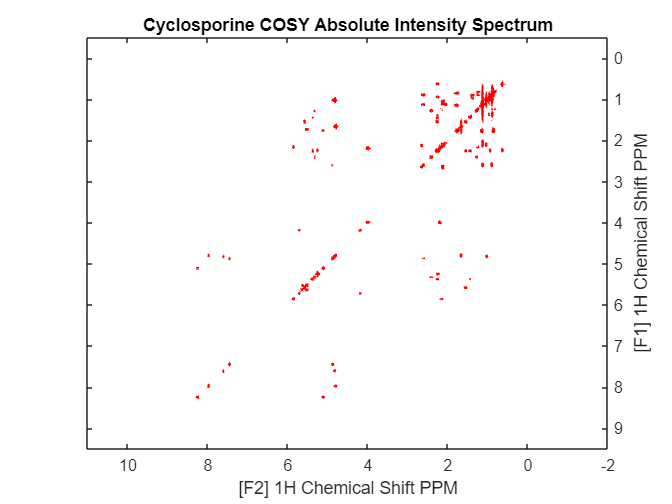

% Enhance the sensitive of the contour plot here
abs_levels=0.95*smax_abs*linspace(0,1,20).^2+0.005*smax_abs;
contour(data.XAxis,data.YAxis,abs((fft2((timeSpectrum)))),abs_levels,'Color','r');
set(gca,'XDir','reverse','YDir','reverse','YAxisLocation','right');
title('Cyclosporine COSY Absolute Intensity Spectrum')
xlabel('[F2] 1H Chemical Shift PPM')
ylabel('[F1] 1H Chemical Shift PPM')
hold on;

However, by zooming into the peaks we can notice some artifacts and noise which causes the signals to overlap. We can reduce these with appropriate [apodization](https://web.stanford.edu/group/chem-NMR/help_docs/2dapodization.htm).

### **Apodization**

Let us try an exponential decay function which enhances the signal-to-noise ratio and broadens our peak shapes. It is applied to the FID data to selectively attenuate the later points in the FID, which are more prone to noise. As a result, the initial, more signal-rich parts of the FID are emphasized. It significantly enhances weaker signals, making them more discernible in the 2D COSY spectrum. This will make our peaks much more easily observable. The plot of the exponential window function can be seen on the right. 

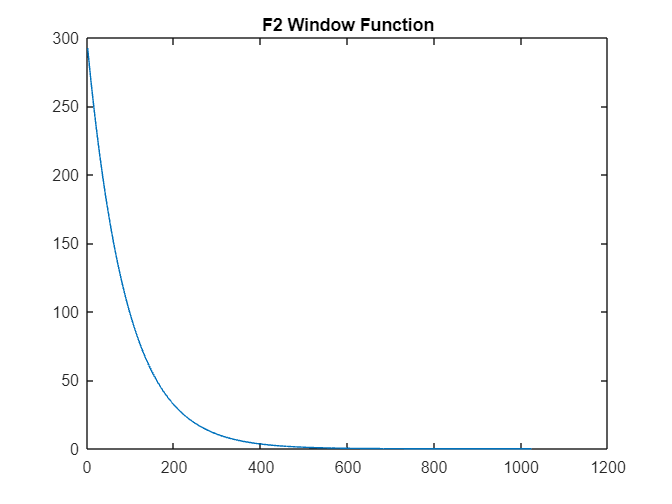

% Apply a exponential decay function
timeSpectrum=expDecayWindowFunction(timeSpectrum,90,'columns');

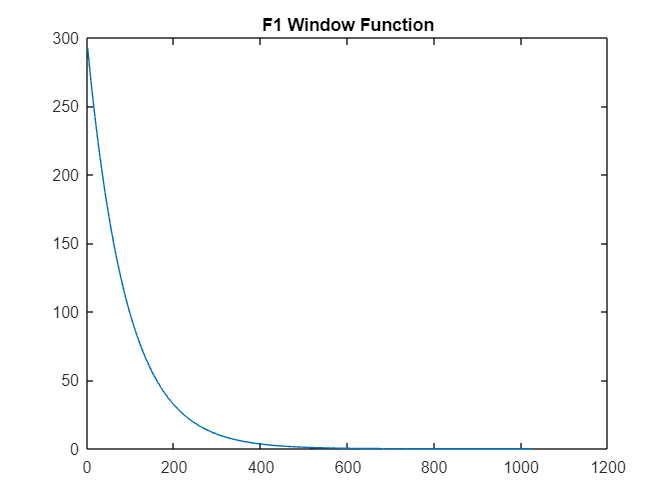

timeSpectrum=expDecayWindowFunction(timeSpectrum,90,'rows');

Apodization is applied to 2D spectra in a similar way to the 1D spectra. However, it now needs to be applied in two dimensions (F2,F1) separately, for each row and column. This is equivalant to applying the window function to each separate 1D FID for each dimension. This can be very easily done by calling a function in MATLAB which requires the time domain spectrum, decay factor, and direction input. The decay (tau) controls our window function.

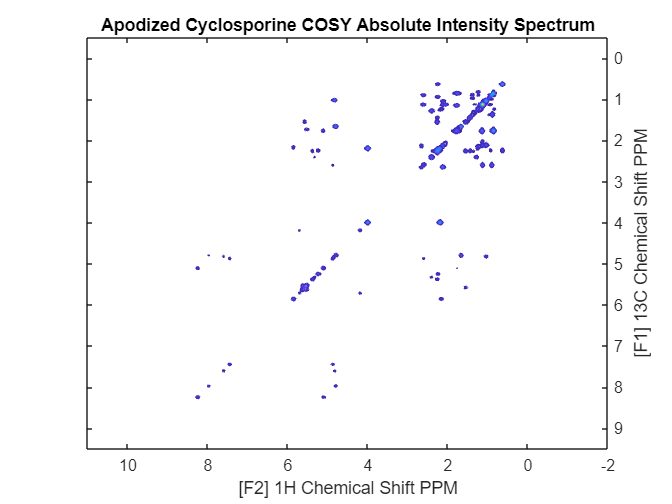

% Go back to frequency domaim
spectrum=fft2(timeSpectrum);

% Plot 2D Contour of COSY
figure()
smax_abs=max(abs(spectrum),[],'all');
abs_levels=0.95*smax_abs*linspace(0,1,20).^2+0.04*smax_abs;
contour(data.XAxis,data.YAxis,abs(spectrum),abs_levels);
set(gca,'XDir','reverse','YDir','reverse','YAxisLocation','right');
xlabel('[F2] 1H Chemical Shift PPM')
ylabel('[F1] 13C Chemical Shift PPM')
title('Apodized Cyclosporine COSY Absolute Intensity Spectrum')
hold on;

By looking at the apodized spectrum we see that the individual cross peaks near the diagonal which had significant overlap are now much more easily visible.

### Summary

In this example, we have explored the processing of 2D NMR COSY (Correlation Spectroscopy) spectra using Cyclosporine as an example. COSY experiments are instrumental in revealing couplings between homonuclear nuclei (like hydrogen atoms) in a molecule. These couplings are manifested as cross peaks in the spectra, providing critical insights into the molecular structure. We have demonstrated how the absolute values of the spectra can be used to show the peaks. In addition to being enhanced with appropriate apodization functions. In this case we have used an exponential decay function to make the weaker peaks more prominent.  

### **Utility Functions**

function expDecayWindow = expDecayWindowFunction(fid, tau, dimension)

    switch dimension 
        case 'rows'
            numberPoints=numel(fid(:,1));
            phiGrid=linspace(1,numberPoints,numberPoints)';

            % Generate Exp Window
            expDecayWindow = exp(-(phiGrid - numberPoints/2) ./ tau);

            % Lets see the window function
            figure()
            plot(expDecayWindow)
            title('F1 Window Function')
            
            % Apply Sine Window to the FID
            expDecayWindow=fid.*expDecayWindow;
        case 'columns'
            numberPoints=numel(fid(1,:));
            phiGrid=linspace(1,numberPoints,numberPoints)';

            % Generate Exp Window
            expDecayWindow = exp(-(phiGrid - numberPoints/2) ./ tau);

            % Lets see the window function
            figure()
            plot(expDecayWindow)
            title('F2 Window Function')

            % Apply Sine Window to the FID
            expDecayWindow=fid.*expDecayWindow';
    end
end